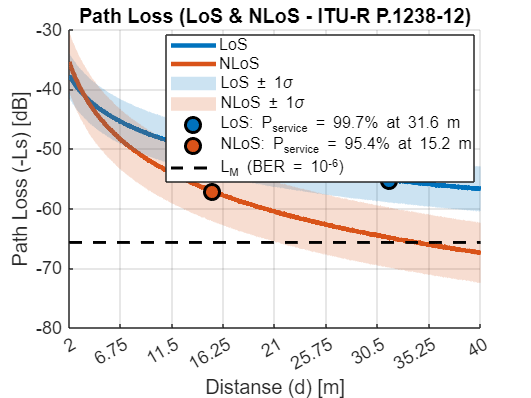

clc; clear; close all;

% Konstanter
c = 3e8;              % Lysfart (m/s)
f = 863e6;            % Frekvens (Hz)
lambda = c / f;       % Bølgelengde (m)

% Avstandsvektor
d = linspace(2, 40, 1000);   % Fra 2 m til 40 m

% ITU-R P.1238-12 parametere for kontor
% Line-of-Sight (LoS)
alpha_LoS = 1.46;
beta_LoS  = 34.62;
gamma_LoS = 2.03;
sigma_LoS = 3.76;  % Fading standardavvik (dB)

% Non-Line-of-Sight (NLoS)
alpha_NLoS = 2.46;
beta_NLoS  = 29.53;
gamma_NLoS = 2.38;
sigma_NLoS = 5.04;  % Fading standardavvik (dB)

% Beregn path loss (dB) for LoS og NLoS
PL_LoS = 10 * alpha_LoS * log10(d) + beta_LoS + 10 * gamma_LoS * log10(f/1e9);
PL_NLoS = 10 * alpha_NLoS * log10(d) + beta_NLoS + 10 * gamma_NLoS * log10(f/1e9);

% Generer stokastisk shadowing
num_realizations = 1e4;  % Antall realisasjoner
X_LoS = sigma_LoS * randn(num_realizations, length(d));
X_NLoS = sigma_NLoS * randn(num_realizations, length(d));

% Totalt path loss med Fading
PL_LoS_total = PL_LoS + X_LoS;
PL_NLoS_total = PL_NLoS + X_NLoS;

% Beregn middelverdi og std med fading
PL_LoS_mean_fading = mean(PL_LoS_total, 1);
PL_LoS_std_fading = std(PL_LoS_total, 1);
PL_NLoS_mean_fading = mean(PL_NLoS_total, 1);
PL_NLoS_std_fading = std(PL_NLoS_total, 1);

% --- Beregn sannsynlighet for mottatt signal P_service ---
% Gitte parametere
EIRP = -20.5;         % dBW (Sendereffekt)
L0 = 6;               % Systemtap (dB)
N0 = -156.2;          % Støytetthet (dBW/Hz)
Gr = 2.0;             % Mottakerantennens vinning (dBi)
Rb = 55.5;            % Bitrate (dBHz)

BER = 1e-6;           % Ønsket bitfeilrate for beregningene

Eb_N0 = 10 * log10( (qfuncinv(BER)).^2 / 2 );

% Maksimalt tillatt path loss (LM)
LM = EIRP - L0 - N0 + Gr - Rb - Eb_N0;

% Beregn sannsynlighet P_service for LoS og NLoS med small-scale fading
P_service_LoS_fading = normcdf(repmat(LM, 1, length(d)), repmat(PL_LoS_mean_fading, length(LM), 1), repmat(PL_LoS_std_fading, length(LM), 1));
P_service_NLoS_fading = normcdf(repmat(LM, 1, length(d)), repmat(PL_NLoS_mean_fading, length(LM), 1), repmat(PL_NLoS_std_fading, length(LM), 1));

% --- Finn punktene der P_service >= 95.4 % for LoS og NLoS ---
P_target_LoS = 0.997;  % Mål for P_service
P_target_NLoS = 0.954;

% For LoS
idx_LoS = find(P_service_LoS_fading <= P_target_LoS, 1, 'first');  % Første punkt hvor P_service >= 95.4% for LoS
d_LoS = d(idx_LoS);  % Finn avstanden for LoS ved dette punktet
PL_LoS_at_P_target = -PL_LoS_mean_fading(idx_LoS);  % Path loss ved dette punktet

% For NLoS
idx_NLoS = find(P_service_NLoS_fading <= P_target_NLoS, 1, 'first');  % Første punkt hvor P_service >= 95.4% for NLoS
d_NLoS = d(idx_NLoS);  % Finn avstanden for NLoS ved dette punktet
PL_NLoS_at_P_target = -PL_NLoS_mean_fading(idx_NLoS);  % Path loss ved dette punktet

% --- PLOT ---
figure;
hold on;
grid on;

% Plot middelverdiene etter small-scale fading
plot(d, -PL_LoS_mean_fading, 'LineWidth', 3, 'DisplayName', 'LoS');
plot(d, -PL_NLoS_mean_fading, 'LineWidth', 3, 'DisplayName', 'NLoS');

% Antall sigma
n = 1;  % ±n sigma
% Skygge rundt middelverdien (±n standardavvik for LoS og NLoS etter fading)
fill([d, fliplr(d)], -[PL_LoS_mean_fading + n * PL_LoS_std_fading, fliplr(PL_LoS_mean_fading - n * PL_LoS_std_fading)], ...
     [0, 0.447, 0.741], 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', sprintf('LoS ± %d\\sigma', n));
fill([d, fliplr(d)], -[PL_NLoS_mean_fading + n * PL_NLoS_std_fading, fliplr(PL_NLoS_mean_fading - n * PL_NLoS_std_fading)], ...
     [0.850, 0.325, 0.098], 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', sprintf('NLoS ± %d\\sigma', n));

% Plot de funnet punktene der P_service ≥ 95.4 %
plot(d_LoS, PL_LoS_at_P_target, 'ko', 'MarkerFaceColor', [0, 0.447, 0.741], 'MarkerSize', 10, 'DisplayName', sprintf('LoS: P_{service} = %.1f%% at %.1f m', P_target_LoS*100, d_LoS),'LineWidth',2);
plot(d_NLoS, PL_NLoS_at_P_target, 'ko', 'MarkerFaceColor', [0.850, 0.325, 0.098], 'MarkerSize', 10, 'DisplayName', sprintf('NLoS: P_{service} = %.1f%% at %.1f m', P_target_NLoS*100, d_NLoS),'LineWidth',2);

% Plot LM-linjen som representerer BER = 1e-6
plot(d, repmat(-LM, size(d)), 'k--', 'LineWidth', 2, 'DisplayName', 'L_M (BER = 10^{-6})');

% Aksetilpasning
xlabel('Distanse (d) [m]', 'FontSize', 14);
ylabel('Path Loss (-Ls) [dB]', 'FontSize', 14);
xlim([min(d), max(d)]);
xticks([linspace(min(d), max(d), 9)]);
title('Path Loss (LoS & NLoS - ITU-R P.1238-12)', 'FontSize', 16);
legend('Location', 'best');
set(gca, 'FontSize', 12);
hold off;